# Notes regarding lab format

We will use Matlab Livescript for this lab. Livescript allows switching between text and code cells. 

You will find the entire lab manual in this file. Some exercises require you to write a text answer, others require you to write code. You should not define functions inside this file. Instead save functions to the functions folder and call them from the code cells in this notebook.

Your finished lab report should be a .zip-file containing the data folder, your functions folder and this livescript file. As usual, you should also provide a pdf of the result of running the live script (in the Live Editor, you can **export to pdf** under Save) where all result images should be visible.

Since we need to access the functions and data folder the first step is to add these two locations MATLAB's path.

addpath('./functions');
addpath('./data');

# **Lab 4 - Triangulation**

## **Using RANSAC**

This whole lab is basically concerned with the camera equation


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\lambda u=P\;U$$


For the uncalibrated case, $u$ is a 3-vector with the coordinates of a point in the image (and an added 1)


$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;u=\left\lbrack \begin{array}{c}
x\\
y\\
1
\end{array}\right\rbrack$$


and $U$ is a 4-vector containing the coordinates of the corresponding 3D point along with a 1 in its last element. A function

sigma = 0.5;
[Ps, us, U_true] = triangulation_test_case(sigma)

Ps = 1×2 cell array
    {3×4 double}    {3×4 double}


us =  -164.2727 -349.5177
 -409.9843 -300.8488


U_true =     0.1264
    0.0734
    0.7668


is provided for creating a simple test case where you know the correct answer (`U_true`). Gaussian noise of standard deviation `sigma` is added to the image points. Use this example to evaluate your minimal solver.

**Ex 4.1**     Make a minimal solver for the triangulation problem, that is, a function 

U = minimal_triangulation(Ps, us)

U =     0.1268
    0.0748
    0.7557


that takes two camera matrices, `Ps`, and two image points, `us`, and triangulates a 3D point. The image points are a 2 x 2 array whereas the camera matrices is a cell list with one camera matrix in each cell. 

Recall that $\lambda$ is the *depth*. Points with negative depth would lie behind the camera, so negative depths indicate that something is wrong.

**Ex 4.2**     Make a function 

positive = check_depths(Ps, U)

positive =      1     1


that takes *N* camera matrices, `Ps`, and a 3D point, `U`, and checks the depth of `U` in each of the cameras. The output should be a an array of boolean values of length *N* that indicates which depths were positive. (Matlab will print boolean values as zeros and ones, so don’t be confused by this.)

**Ex 4.3**     Make a function 

errors = reprojection_errors(Ps, us, U)

errors =     0.4967
    0.5883


that takes *N* camera matrices, `Ps`, *N* image points, `us`, and a 3D point, `U`, and computes a vector with the reprojection errors, that is, the lengths of the reprojection residuals. If a point has negative depth, set the reprojection error to `Inf`. 

**Ex 4.4**     Make a function 

threshold =  2

threshold = 2

[U, nbr_inliers] = ransac_triangulation(Ps, us, threshold) 

U =     0.1268
    0.0748
    0.7557


nbr_inliers = 2

that implements triangulation using RANSAC. Use the number of outliers as loss function. A measurement is deemed as an outlier if the depth is negative or if the reprojection error is larger than `threshold`. 

In `sequence.mat` you find a struct array `triangulation_examples` with triangulation examples. Each example (3D point) has a cell list of camera matrices `Ps` and a 2 x N-array `us` with image points. It will take some time to triangulate all 32183 examples so start with the first 1000 or so. We used a RANSAC threshold of 5 pixels. 

**Ex 4.5**     Make a script `triangulate_sequence` that runs `ransac_triangulation` for all (or at least 1000) of the examples from `sequence.mat`. Store all triangulated points with at least two inliers and plot them using `scatter3`. There will always be a few outliers among the estimated 3D points that make it harder to view the plot. You can use the provided `clean_for_plot.m` to clean it up a bit. 

triangulate_sequence   % Script that you need to create

Uc = clean_for_plot(Us) 

Uc =   -17.5935  -18.2169  -15.7878  -14.1047  -16.7109  -16.5074  -14.9087  -17.9632  -17.2111  -16.6138  -14.5106  -12.6594  -12.6177  -12.6105  -12.9907  -17.6792  -17.7910  -17.5111  -16.9431  -12.6826  -13.0223  -13.1002  -18.3473  -18.1437  -17.2422  -17.1362  -17.0451  -16.9344  -16.9153  -16.7848  -15.6583  -12.5855  -13.0568  -13.0003  -13.1318  -12.9207  -18.3848  -18.2658  -18.0159  -17.8788  -17.5112  -17.5782  -17.3988  -17.3724  -17.4006  -17.4006  -17.2958  -17.1698  -17.1685  -17.1277
    4.7296    5.0394    5.3788    5.7166    5.2661    5.2593    5.5337    5.2592    5.4943    5.4483    5.7174    2.1579    2.4136    2.4635    5.0748    5.2826    5.2420    5.3707    5.3608    3.1615    5.0598    6.1040    5.1489    5.1942    5.6194    5.5839    5.5688    5.5951    5.5691    5.3501    5.4896    3.2398    5.3395    5.3317    5.7406    5.8645    5.0521    5.2396    5.1821    5.6029    5.3527    5.2884    5.4496    5.5071    5.2386    5.2552    5.5985    5.5476    5.5883    

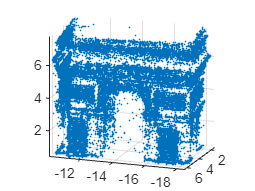

scatter3(Uc(1,:),Uc(2,:),Uc(3,:),0.5,'.') 
axis equal
view([-159.8 16.3])

Can you recognize the building? 

**Write your answer with explanation as a comment here.**

% It looks like the Arc de Triomphe

## Least squares triangulation 

In this part of the lab you will solve the tringulation problem through least squares. Just as in the case of registration, the following pipeline is recommended: 

    - Use RANSAC to obtain a rough estimate of the parameters (*U*). 

    - Remove all measurements which are outliers with respect to these parameters. 

    - Estimate the least squares parameters using the remaining measurements. 

Note that in this case a *measurement* is a pair consisting of an image point $u_i$ and a camera matrix $P_i$. Don’t forget that points with negative depths should be outliers. 

**Ex 4.6**     Consider a camera matrix 

                        $P_i =\left\lbrack \begin{array}{c}
\longleftarrow a_i^T \longrightarrow \\
\longleftarrow b_i^T \longrightarrow \\
\longleftarrow c_i^T \longrightarrow 
\end{array}\right\rbrack$ ,

a 3D point *U* and an image point $u_i$. Write the formula for the reprojection error $r_i \left(U\right)$ below.

**Your answer here:**


$$r_i \left(U\right)=\left\lbrack \begin{array}{c}
\frac{a_i^T U}{c_i^T U}-x_i \\
\frac{b_i^T U}{c_i^T U}-y_i 
\end{array}\right\rbrack ,u_i =\left(x_i \;,y_i \;\right)$$


As you can see, the residuals are no longer linear, so computing a least squares solution will be significantly harder than in the previous lab. In fact, we cannot be sure to find the least squares solution. What we can do is to use local optimization to reduce the sum of squared residuals. We start at the solution produced by Ransac and use a few Gauss-Newton iterations.

**Ex 4.7**     Make a function  

that takes a cell list `Ps` with *N* cameras, a 2 x *N* array `us` of image points and a 3 x 1 array `U`, and computes a 2*N* x 1 array with all the reprojection residuals stacked into a single vector/array. A reprojection residual is a 2D vector corresponding to the difference between the original measurement and the projected point. The stacked vector is the $\bar{r}$ from the lecture notes (page 99).

% usage example
points3D = triangulation_examples;
all_residuals = compute_residuals(points3D(1).Ps, points3D(1).xs, Us(:,1))

all_residuals =    -9.9118
   10.6550
   -2.0682
    6.6203
   -1.1280
    0.2160
    1.1191
   -0.2219
   -0.1734
   -5.0447


**Ex 4.8**     Find formulas for the partial derivatives in the Jacobian of $\bar{r}$. The Jacobian should be a 2N x 3- matrix. (Hint: you can start by finding the formula to the Jacobian of the i-th residual, which is a 2x3 matrix.)

## Your answer here:


$$J_i =\left\lbrack \begin{array}{c}
\frac{a_i^T \left(c_i^T U\right)-\left(a_i^T U\right)c_i^T }{{\left(c_i^T U\right)}^2 }\\
\frac{b_i^T \left(c_i^T U\right)-\left(b_i^T U\right)c_i^T }{{\left(c_i^T U\right)}^2 }
\end{array}\right\rbrack$$
 

To form the entire Jacobian we can stack each Jacobian of the i-th residual

**Ex 4.9**     Make a function 

that computes the Jacobian given a 3 x 1- vector `U` and a cell array of camera matrices `Ps`. 

% usage example
all_residuals = compute_jacobian(points3D(1).Ps, Us(:,1))

all_residuals =   -17.6347   76.7025  152.5401
 -168.0825  -16.4956   -8.0095
  -24.9332   77.9027  155.1379
 -169.7658  -25.9685  -10.3364
  -29.3503   73.4454  152.2063
 -165.4660  -33.4634  -11.4853
  -30.1584   71.6349  151.6649
 -163.0136  -39.9526   -9.1677
  -30.8262   72.2793  152.5887
 -162.9345  -44.6100   -7.5493


**Ex 4.10**     Use these functions to make a function 

that uses an approximate 3D point `Uhat` as a starting point for Gauss-Newton’s method. Use five GaussNewton iterations. Print the sum of squared residuals after each Gauss-Newton step to verify that it decreases. 

% usage example
Uref = refine_triangulation(points3D(1).Ps, points3D(1).xs, Us(:,1))

Uref =   -17.4131
    3.8202
    6.7842


**Ex 4.11**     Try your `refine_triangulation` on the data in `gauss_newton.ma`t. First we will plot the points given in `Uhat`, then refine each point using your function and plot the results using `scatter3`. You should see an improvement. 

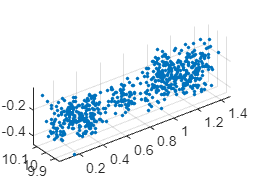

% don't forget to plot your results
load gauss_newton
scatter3(Uhat(1,:),Uhat(2,:),Uhat(3,:),'.') 
axis equal

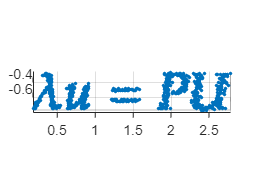


Ps = {P,P_tilde};

N = size(Uhat,2);
Uref = zeros(3,N);
for i = 1:N
    Uref(:,i) = refine_triangulation(Ps, [u(:,i), u_tilde(:,i)], Uhat(:,1));
end
scatter3(Uref(1,:),Uref(2,:),Uref(3,:),'.') 
axis equal

view([-0.05 5.13])

**Ex* 4.12**     Compute the camera positions for the data in `gauss_newton.mat` and plot them together with the estimated 3D points. Try to understand why the noise in the estimated points looks as it does. 

% YOUR CODE HERE; don't forget to plot your results
N_cameras = length(Ps);

c = zeros(4, N_cameras);
v = zeros(3, N_cameras);
for i=1:N_cameras
    
    c(:,i) = null(Ps{i});
    v(:,i) = Ps{i}(3,1:3);

end

c = c./repmat(c(4,:),[4 1]);

disp('First Camera')

First Camera


disp(['Center',char(9),char(9),char(9),char(9),'Main Axis'])

Center				Main Axis


disp([num2str(c(1:3,1)'),char(9),char(9),char(9),char(9),num2str(v(:,1)')])

0  0  0				0  1  0



disp('Second Camera')

Second Camera


disp(['Center',char(9),char(9),char(9),char(9),'Main Axis'])

Center				Main Axis


disp([num2str(c(1:3,2)'),char(9),char(9),char(9),char(9),num2str(v(:,2)')])

0.83205  1.1175e-16      0.5547				0.049602      0.9964    0.068803


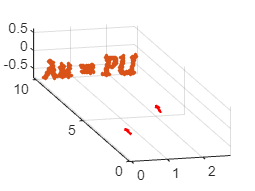


quiver3(c(1,:),c(2,:),c(3,:),v(1,:), v(2,:), v(3,:),['r','-'],'LineWidth',1.5,'MaxHeadSize',1.5);
hold on
scatter3(Uref(1,:),Uref(2,:),Uref(3,:),'.') 
axis equal
hold off

view([-14.66 13.23])

For the next exercise try the following way to match features, 

The approximate option makes it go significantly faster. A Lowe ratio of 0.9 is very high, but it makes the model more *dens*e. 

**Ex 4.13**     There are images `duomo.jpg` and `duomo_tilde.jpg` in the lab folder and also a data file `duomo.mat` with two camera matrices. Extract SIFT features from the two images using `detectSIFTFeatures` and `extractFeatures`, then match them using `matchFeatures`. Also store the color of each SIFT point. It doesn’t matter from which of the images you select the color information. 

Use your triangulation code (don’t forget r`efine_triangulation`) to triangulate the points and plot them with the right color using `scatter3`. Again, you can use `clean_for_plot.m` to remove outliers among the estimated 3D points. Beware that triangulating all the points will take a little time so work with a subset until you are sure that the code works. 

% Your code here
load duomo
A_img = imread("duomo.jpg");
B_img = imread("duomo_tilde.jpg");
A = rgb2gray(A_img);
B = rgb2gray(B_img);

points_A = detectSIFTFeatures(A);
[d1, validPointsA] = extractFeatures(A,points_A);

points_B = detectSIFTFeatures(B);
[d2, validPointsB] = extractFeatures(B,points_B);

matches = matchFeatures(d1,d2,'Method','Approximate','MaxRatio',0.9,'MatchThreshold',100);

u = validPointsA(matches(:,1)).Location';

u_tilde = validPointsB(matches(:,2)).Location';

Ps = {P,P_tilde};
threshold = 10;
Us = [];
N_examples = length(matches);
inliers = [];
for i=1:N_examples

    xs = [u(:,i) , u_tilde(:,i)];
    
    [U, nbr_inliers] = ransac_triangulation(Ps, xs, threshold);

    if nbr_inliers >=2
        Us = [Us U];
        inliers = [inliers, i];
    end

end

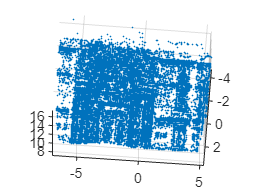

Uc = clean_for_plot(Us);
scatter3(Uc(1,:),Uc(2,:),Uc(3,:),0.5,'.') 
axis equal

view([-4.35 -69.21])

warning('off','all')
Uhat = Us;
N = length(inliers);
Uref = zeros(3,N);
for i = 1:N
    idx = inliers(i);
    Uref(:,i) = refine_triangulation(Ps, [u(:,idx), u_tilde(:,idx)], Uhat(:,1));
end

Uref = clean_for_plot(Uref);

u = Ps{1}*[Uref;ones(1,size(Uref,2))];
u = u(1:2,:)./u(3,:);

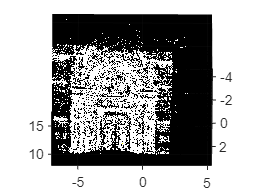

n_points = size(u,2);
colors = [];
for i=1:n_points
    colors = [colors, sample_image_at(A_img,u(:,i))];
end
scatter3(Uref(1,:),Uref(2,:),Uref(3,:),0.5,colors','filled')
set(gca,'color',[0 0 0])
axis equal

view([-0.19 -64.08])

N_cameras = length(Ps);

c = zeros(4, N_cameras);
v = zeros(3, N_cameras);
for i=1:N_cameras
    
    c(:,i) = null(Ps{i});
    v(:,i) = Ps{i}(3,1:3);

end

c = c./repmat(c(4,:),[4 1]);

disp('First Camera')

First Camera


disp(['Center',char(9),char(9),char(9),char(9),'Main Axis'])

Center				Main Axis


disp([num2str(c(1:3,1)'),char(9),char(9),char(9),char(9),num2str(v(:,1)')])

0  0  0				0  0  1



disp('Second Camera')

Second Camera


disp(['Center',char(9),char(9),char(9),char(9),'Main Axis'])

Center				Main Axis


disp([num2str(c(1:3,2)'),char(9),char(9),char(9),char(9),num2str(v(:,2)')])

-0.9599    -0.28032  -0.0021199				-1.5368e-05   -0.020681     0.99979


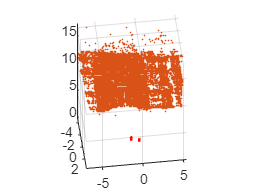


quiver3(c(1,:),c(2,:),c(3,:),v(1,:), v(2,:), v(3,:),['r','-'],'LineWidth',1.5,'MaxHeadSize',1.5);
hold on
scatter3(Uref(1,:),Uref(2,:),Uref(3,:), 0.5,'.') 
axis equal
hold off

view([7.0 -48.0])

## **Essential Matrix**

The two exercises below are optional and therefore marked with *****.

**Ex* 4.14**     Load the data in `P.mat`. There you will find two calibrated camera matrices, `P1` and `P2`. Make a function 

that computes the essential matrix `E` from `P1` and `P2` .

load P.mat


**Ex* 4.15**     Similar to the reprojection error in the triangulation problem, the essential matrix can also be used for outlier detection using the residual


$$r^2 =\frac{\left|{\tilde{x} }^T \;E\;x\;\right|}{{\left\|S\;E\;x\right\|}^2 +{\left\|S\;E^T \;\;\tilde{x} \right\|}^2 \;},\;\;\;\;\;\;\;\;\;\;S=\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$$


where $x$ and $\tilde{x}$ are the image projections of a 3D point *X* using some arbitrary camera matrices $P$ and $\tilde{P}$, respectively. Note that $r$ does not depend on X. Assuming that you are using a similar threshold for outlier detection, for a set of pixel correspondences, you would get `I1` inliers if you use the residual from the triangulation problem and `I2` inliers if you used the residual from (4.4). Which one is greater, `I1` or `I2`? Why? 